# `MATH 3620 Numerical Analysis`

# `Homework 9`

# `24 April 2021`

close all; clear all ; clc;

## `Q1. Boundary Value Problem - Conjugate Gradient Method`

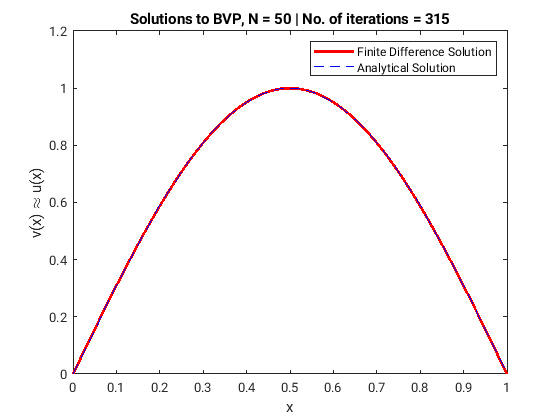

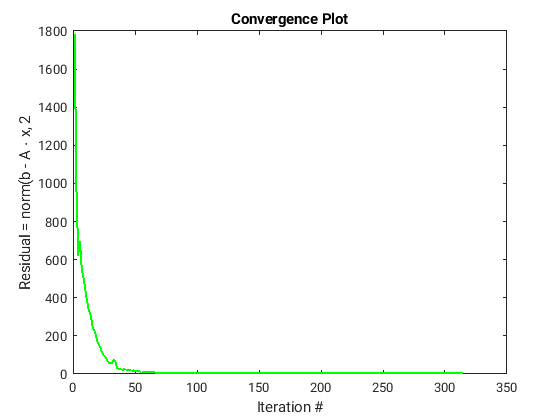

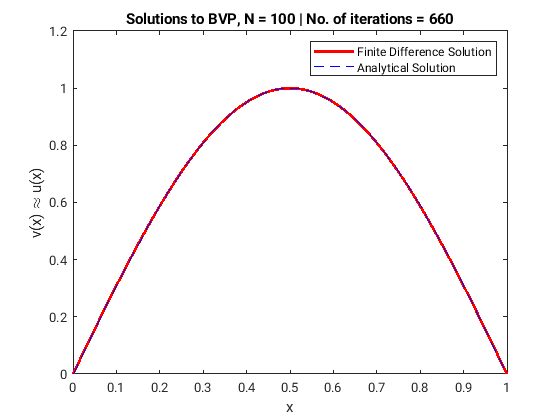

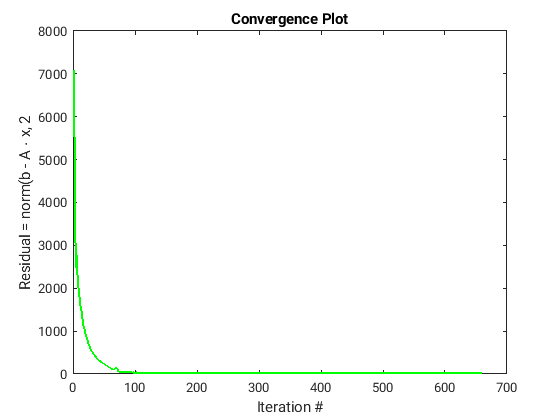

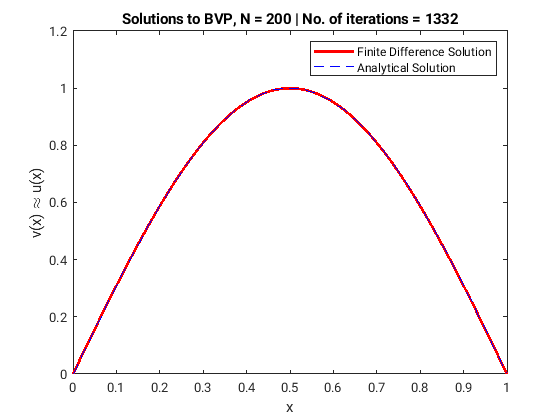

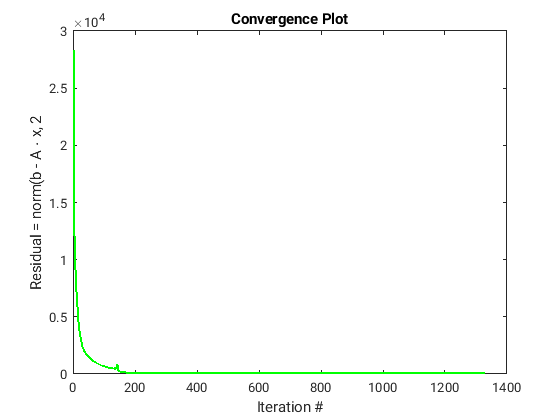

% parameters
a = 0; b = 1;
Nlist = [50, 100, 200]; 

for j = 1:length(Nlist)
    N = Nlist(j);
    h = (b-a)/N;
    
    % domain
    x = a:h:b;
    
    % setup A and b
    A = zeros(N-1, N+1);
    c = 2*(pi^2)*sin(pi*x(2:end-1));
    v1 = 0; vN = 0;
    for i = 2:N 
        A(i-1, i-1) = -1/(h^2);
        A(i-1, i) = (pi^2) + 2/(h^2);
        A(i-1, i+1) = A(i-1, i-1);
    end
    c = c' - v1*A(:, 1) - vN*A(:, end);
    A = A(:, 2:N);
    
    % solve for v using conjugate gradient method
    % initial guess
    u = ones(size(c));
    % initialise
    r = c - A*u; v = r; residual = [];
    TOL = 1e-6; k = 0; maxiter = 1e6;
    while (k < maxiter) && norm(r, 2) > TOL
        t = (r'*r)/(r'*(A*r));
        unew = u + t*v;
        rnew = r - t*A*v;
        snew = (rnew'*rnew)/(r'*r);
        vnew = rnew + snew*v;
        k = k+1;
        
        u = unew;
        r = rnew;
        v = vnew;
        residual = [residual, norm(r, 2)];
    end
    
    v = [v1; u; vN];
    
    % plot solution
    figure()
    plot(x, v, 'r-', 'LineWidth', 2);
    xlabel('x')
    ylabel('v(x) \approx u(x)')
    titlestring = ['Solutions to BVP, N = ', num2str(N), ' | No. of iterations = ', num2str(k)];
    title(titlestring)
    hold on
    plot(x, sin(pi*x), 'b--')
    legend('Finite Difference Solution', 'Analytical Solution')
    hold off
    
    % plot residuals
    figure()
    plot(1:k, residual, 'g-', 'LineWidth', 1.5)
    xlabel('Iteration #')
    ylabel('Residual = norm(b - A \cdot x, 2')
    title('Convergence Plot')
end

`Comments:`` We see that ``the conjugate gradient algorithm converges for all values of N``. The tolerance level is set at 1e-6 and the max. number of iterations allowed are 1e6. The residuals decay quickly and the solution converges to the actual solution as can be seen from the plots above.`

`We also see that the number of iterations required increase in proportion with N. ``As N doubles, so does the number of iterations required.`

## `2a Richardson's Method`

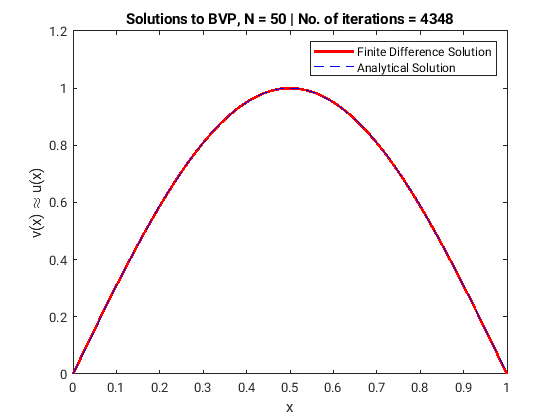

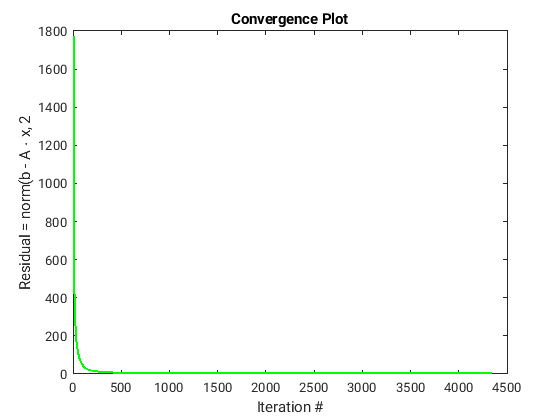

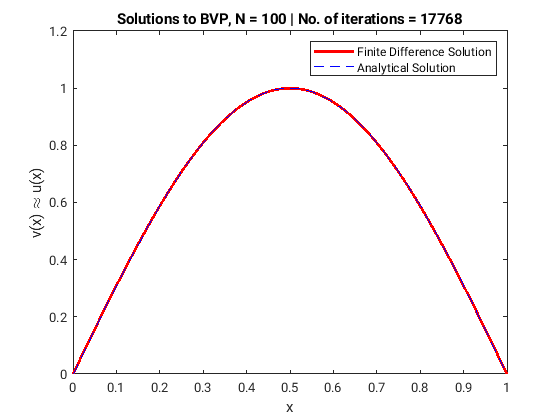

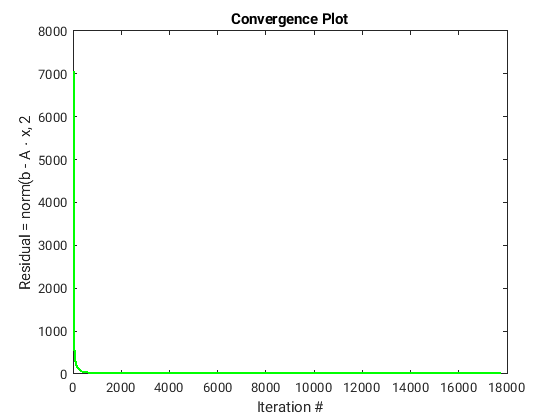

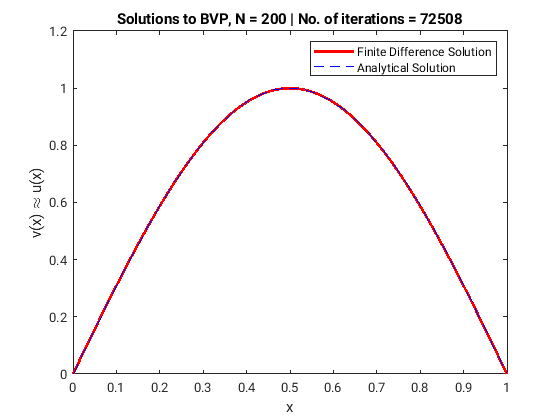

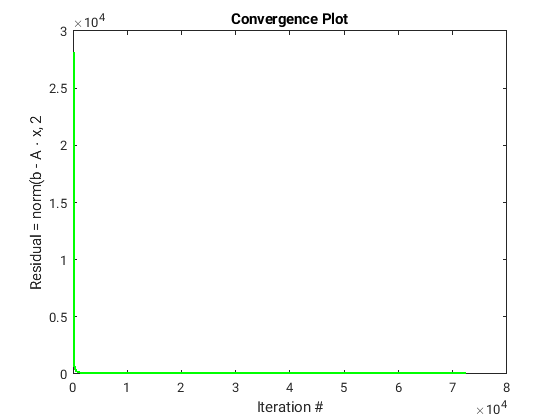

% parameters
a = 0; b = 1;
Nlist = [50, 100, 200]; 

for j = 1:length(Nlist)
    N = Nlist(j);
    h = (b-a)/N;
    
    % domain
    x = a:h:b;
    
    % setup A and b
    A = zeros(N-1, N+1);
    c = 2*(pi^2)*sin(pi*x(2:end-1));
    v1 = 0; vN = 0;
    for i = 2:N 
        A(i-1, i-1) = -1/(h^2);
        A(i-1, i) = (pi^2) + 2/(h^2);
        A(i-1, i+1) = A(i-1, i-1);
    end
    c = c' - v1*A(:, 1) - vN*A(:, end);
    A = A(:, 2:N);
    
    % solve for v using Richardson's method
    % initial guess
    u = ones(size(c));
    % initialise
    r = c - A*u; residual = [];
    TOL = 1e-6; k = 0; maxiter = 1e6;
    % optimal omega (from trial and error)
    omega = 1.99/max(eig(A));
    while (k < maxiter) && norm(r, 2) > TOL
        unew = u + omega*r;
        rnew = c - A*unew;
        k = k+1;
        
        u = unew;
        r = rnew;
        residual = [residual, norm(r, 2)];
    end
    
    v = [v1; u; vN];
    
    % plot solution
    figure()
    plot(x, v, 'r-', 'LineWidth', 2);
    xlabel('x')
    ylabel('v(x) \approx u(x)')
    titlestring = ['Solutions to BVP, N = ', num2str(N), ' | No. of iterations = ', num2str(k)];
    title(titlestring)
    hold on
    plot(x, sin(pi*x), 'b--')
    legend('Finite Difference Solution', 'Analytical Solution')
    hold off
    
    % plot residuals
    figure()
    plot(1:k, residual, 'g-', 'LineWidth', 1.5)
    xlabel('Iteration #')
    ylabel('Residual = norm(b - A \cdot x, 2')
    title('Convergence Plot')
end

## `2b Weighted Jacobi Method`

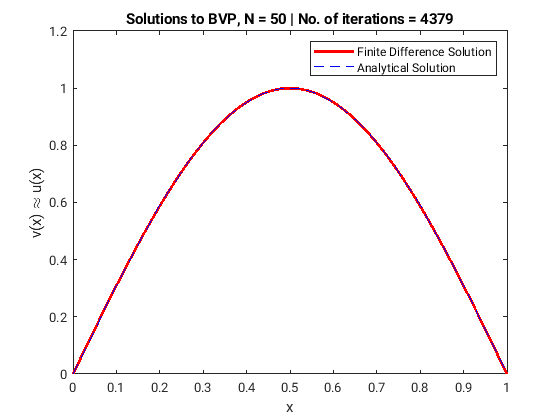

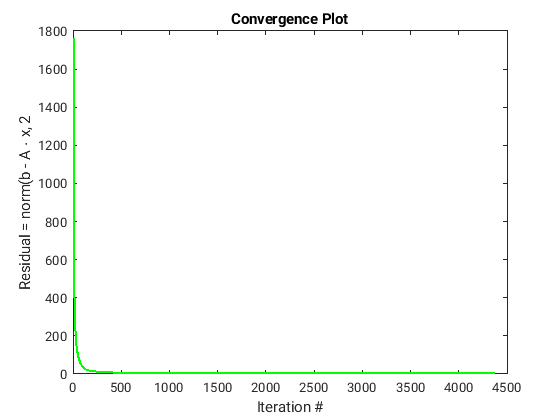

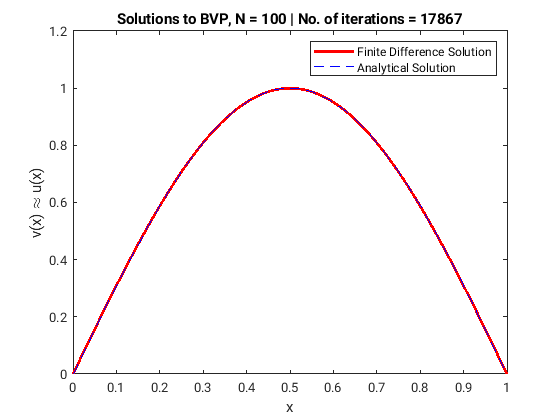

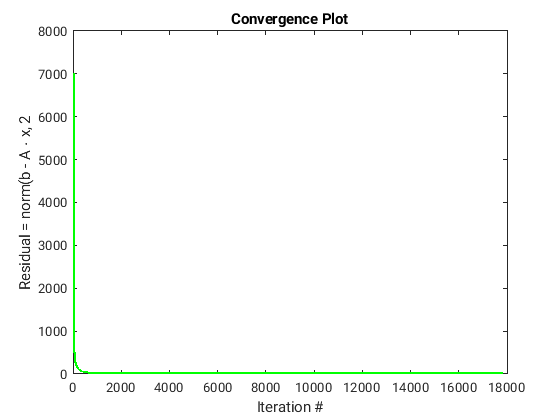

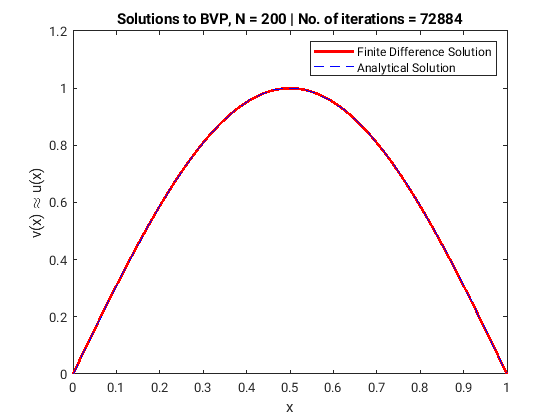

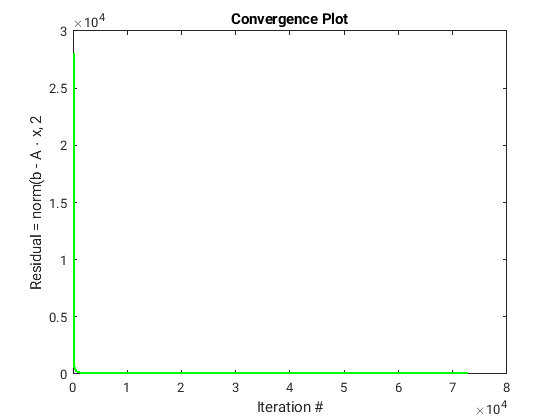

% parameters
a = 0; b = 1;
Nlist = [50, 100, 200]; 

for j = 1:length(Nlist)
    N = Nlist(j);
    h = (b-a)/N;
    
    % domain
    x = a:h:b;
    
    % setup A and b
    A = zeros(N-1, N+1);
    c = 2*(pi^2)*sin(pi*x(2:end-1));
    v1 = 0; vN = 0;
    for i = 2:N 
        A(i-1, i-1) = -1/(h^2);
        A(i-1, i) = (pi^2) + 2/(h^2);
        A(i-1, i+1) = A(i-1, i-1);
    end
    c = c' - v1*A(:, 1) - vN*A(:, end);
    A = A(:, 2:N);
    
    % solve for v using weighted Jacobi method
    % decompose A = D + (L + U)
    D = diag(A).*eye(size(A, 1));
    LplusU = A-D;
    % initial guess
    u = ones(size(c));
    % initialise
    r = c - A*u; residual = [];
    TOL = 1e-6; k = 0; maxiter = 1e6;
    % optimal omega (from trial and error)
    omega = 0.99;
    while (k < maxiter) && norm(r, 2) > TOL
        unew = omega*(D\(c - LplusU*u)) + (1 - omega)*u;
        rnew = c - A*unew;
        k = k+1;
        
        u = unew;
        r = rnew;
        residual = [residual, norm(r, 2)];
    end
    
    v = [v1; u; vN];
    
    % plot solution
    figure()
    plot(x, v, 'r-', 'LineWidth', 2);
    xlabel('x')
    ylabel('v(x) \approx u(x)')
    titlestring = ['Solutions to BVP, N = ', num2str(N), ' | No. of iterations = ', num2str(k)];
    title(titlestring)
    hold on
    plot(x, sin(pi*x), 'b--')
    legend('Finite Difference Solution', 'Analytical Solution')
    hold off
    
    % plot residuals
    figure()
    plot(1:k, residual, 'g-', 'LineWidth', 1.5)
    xlabel('Iteration #')
    ylabel('Residual = norm(b - A \cdot x, 2')
    title('Convergence Plot')
end

## `2c Convergence Plots`

`The convergence plots are displayed above along with the obtained solution. We see that the residuals decay quickly in the beginning. However, it takes a large number of iterations to achieve the tolerance level of 1e-6. The number of iterations required for both the methods are almost equal.`

`For Richardson's method, the max. value of `$\omega$ `is `$2/\rho(A)$`. We start with that value and with trial and error, end up with an optimal value of `$\omega_{opt} = 1.99/\rho(A)$`. This is quite close to the max. value. Also, note that we define the optimal value to be that which results in the least number of iterations.`

`For weighted Jacobi method, we begin with a baseline value of `$\omega = 2/3$ `and through trial and error, end up with an optimal value of `$\omega_{opt} = 0.99$`. This is quite close to 1 and shows that the weighted Jacobi method, in this scenario, performs only marginally better than the Jacobi method. Again, we define the optimal value to be that which results in the least number of iterations. Also, the algorithm converges for values of `$\omega > 1$ `but the solution obtained is not realistic and does not resemble the actual physical solution.`

`Both the algorithms are much slower compared to the conjugate gradient method. Also, in the case of conjugate gradient method, ``# of iterations `$\propto N$`, whereas, for the weighted Jacobi and Richardson's method, ``# of iterations `$\propto N^2$`. As N doubles, the required number of iterations quadruples.`  